## Practice 3. Propagation of state and covariance

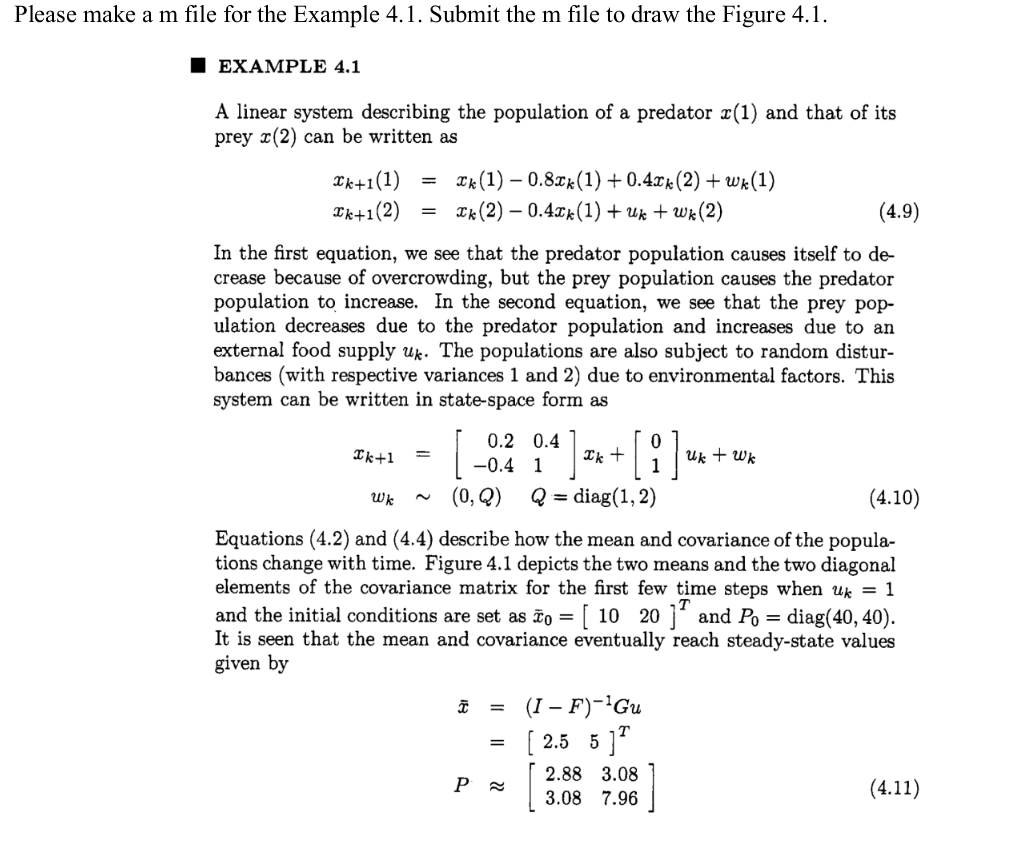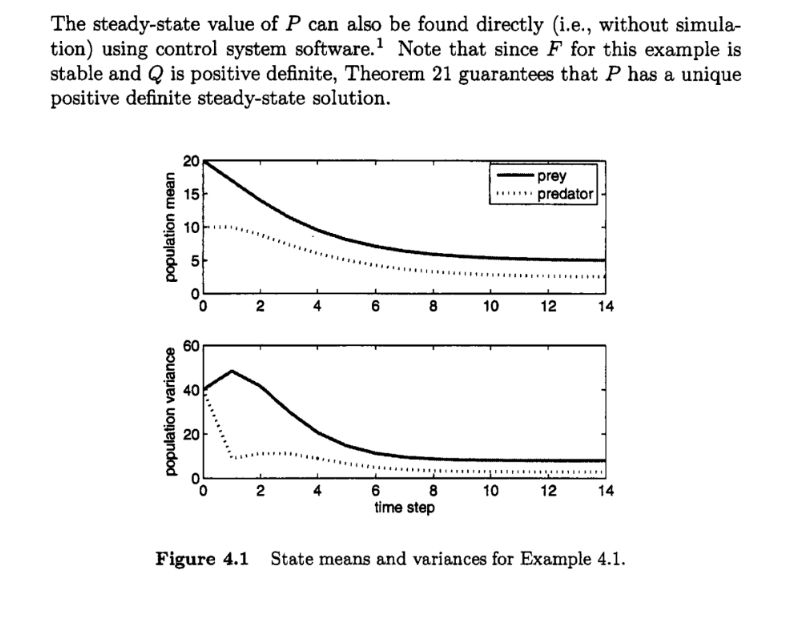

clc; clear; close all;

sim_time = 14;
Num_of_state = 2;

F = [0.2  0.4;
    -0.4   1];

G = [0, 1]';
Q = diag([1, 2]);
u_k = 1;

init_x = [10 20]';
init_P = 40*eye(2);

x = zeros(sim_time, 2);
P = cell(sim_time,1);

isFirstStep = true;
for idxSim = 1:sim_time
    if isFirstStep == true
        x(idxSim,:) = init_x;
        P{idxSim}= init_P;
        isFirstStep = false;
        continue;
    end

    x(idxSim,:) = F * x(idxSim-1,:)' + G*u_k;
    P{idxSim} = F * P{idxSim-1} * F' + Q;

end


% Plot

figure('Name','Practice 3', 'Position',[100,100,840,630]);

time = 1:sim_time;
hold on; 

subplot(2,1,1)
plot(time, x(:,2), '-', time, x(:,1), '--');
legend('prey', 'predator'); ylabel('population variance');
xlim([1 sim_time]);

subplot(2,1,2)
P11 = cellfun(@(p) p(1,1), P);
P22 = cellfun(@(p) p(2,2), P);
plot(time, P22, '-', time, P11, '--');
xlim([1 sim_time]);
xlabel('time step'); ylabel('population variance');

hold off;